
cd('/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224Afterpulse')
nsPerPoint=spc.datainfo.psPerUnit/1000

nsPerPoint = 0.0489

range=round([spc.fits{1,1}.fitstart spc.fits{1,1}.fitend]/nsPerPoint);
baseName = '20221224Afterpulse'

baseName = '20221224Afterpulse'

DarkCount_all = [];

for i = 28:30
    spc_name = [baseName, 'FLIM0', num2str(i), '.mat'];
    load(spc_name);
    DarkCount = sum(spcSave.lifetimes{1});
    DarkCount_all = [DarkCount_all DarkCount];
end

DarkCount_mean = mean(DarkCount_all)

DarkCount_mean = 2.7117e+03

cd('/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224Afterpulse')
numPts=256-8-18;
afterpulse_all = []


afterpulse_all =

     []



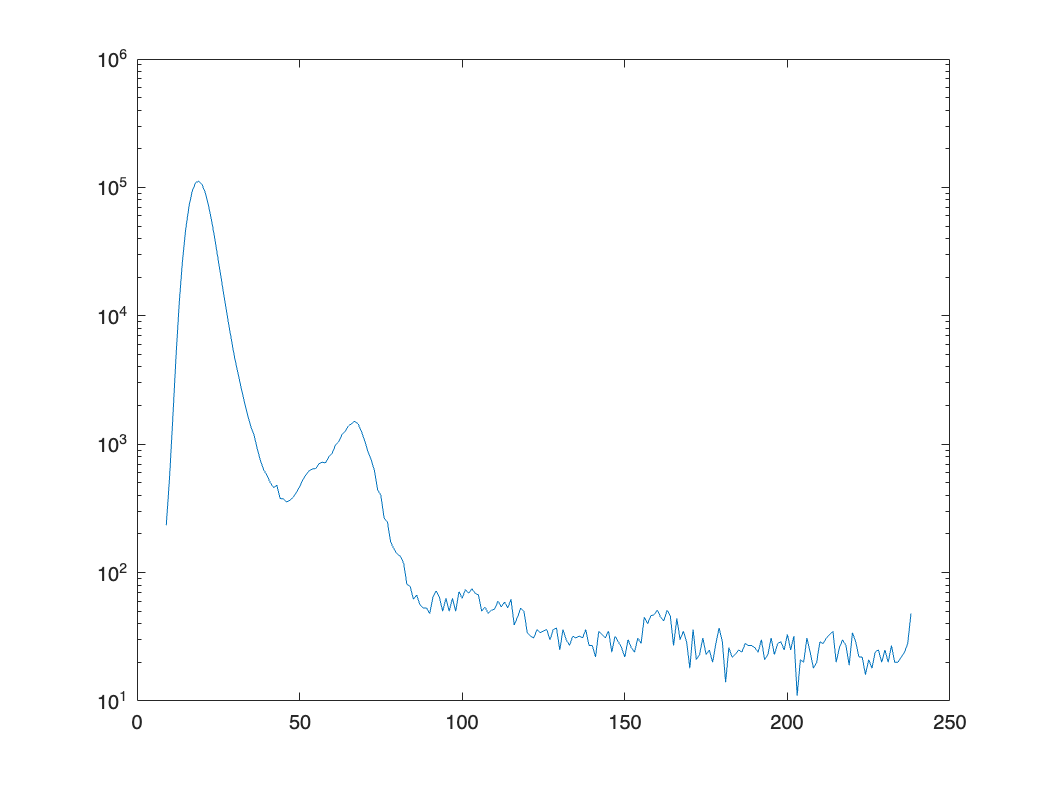

base = 13.4601

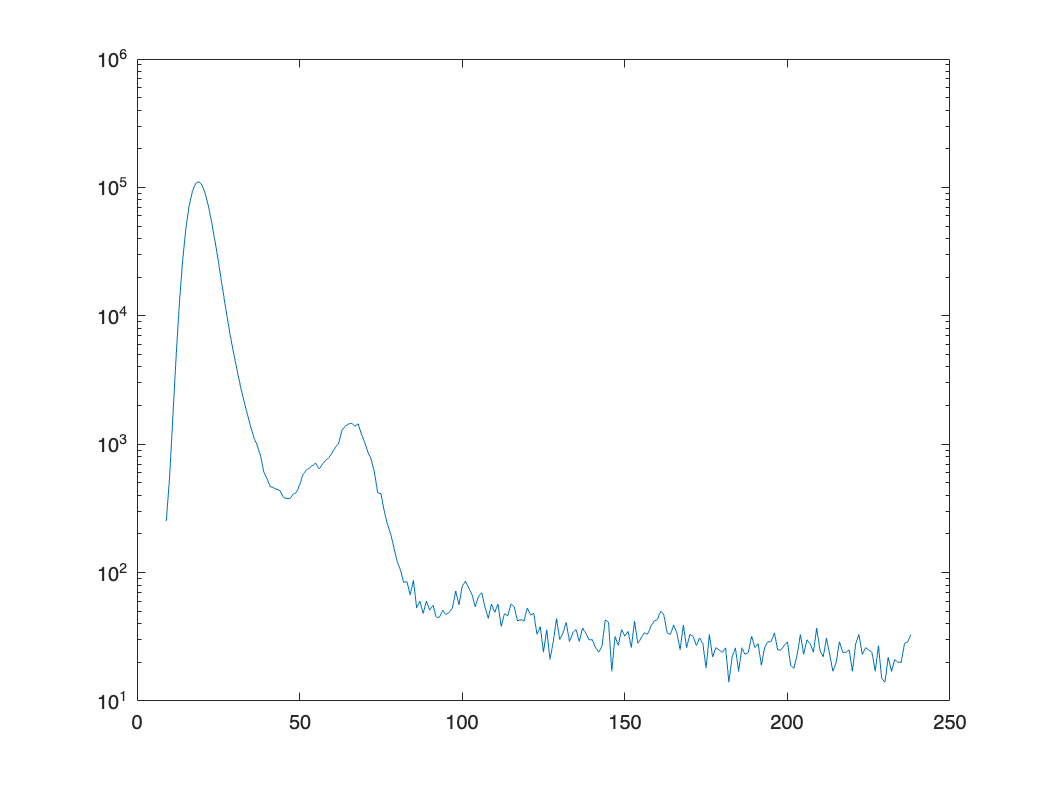

base = 12.7258

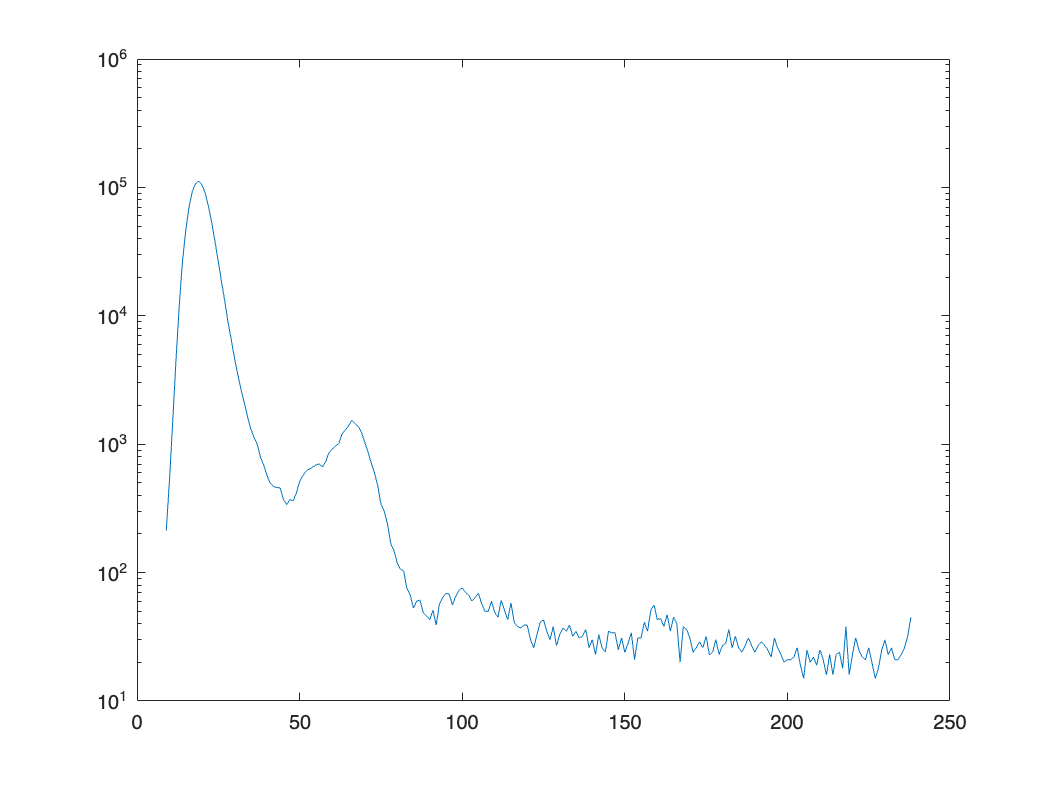

base = 12.7883

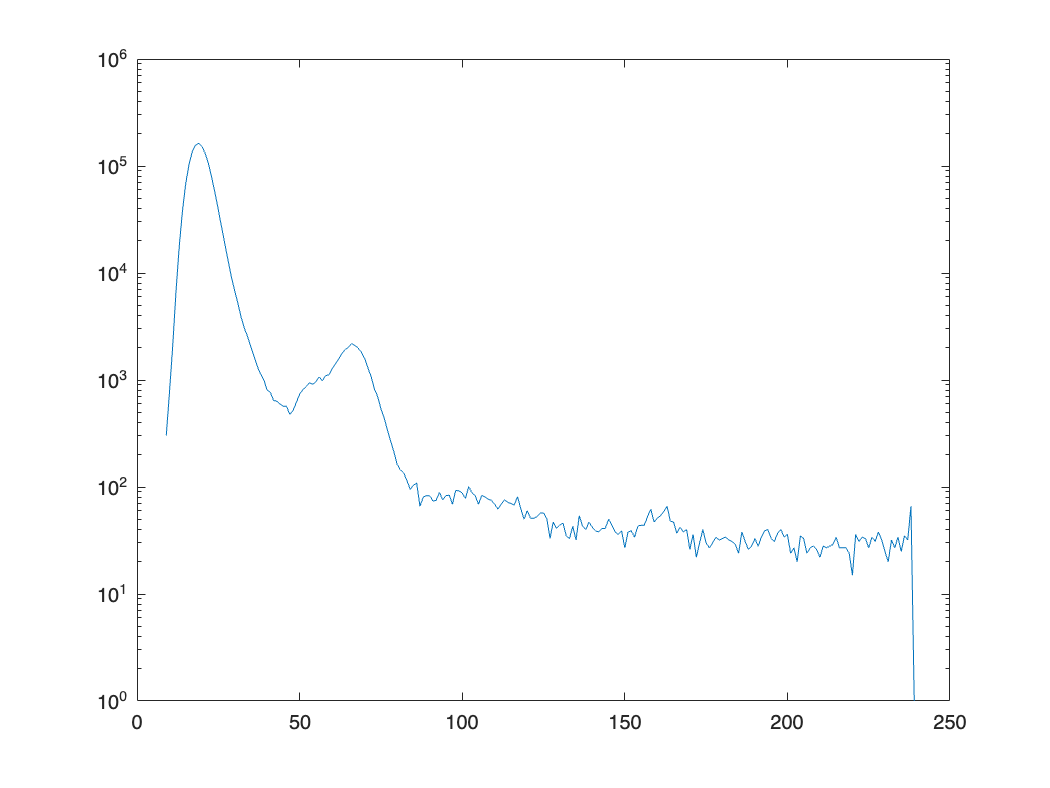

base = 18.9601

for i = 11:14
    spc_name = [baseName, 'FLIM0', num2str(i), '.mat'];
    load(spc_name);
    figure
    semilogy(spcSave.lifetimes{1})
    base=mean(spcSave.lifetimes{1}(175:238))-DarkCount_mean/numPts
    tot=sum(spcSave.lifetimes{1})-numPts*base-DarkCount_mean;
    afterpulse_all = [afterpulse_all numPts*base/tot];
    
end

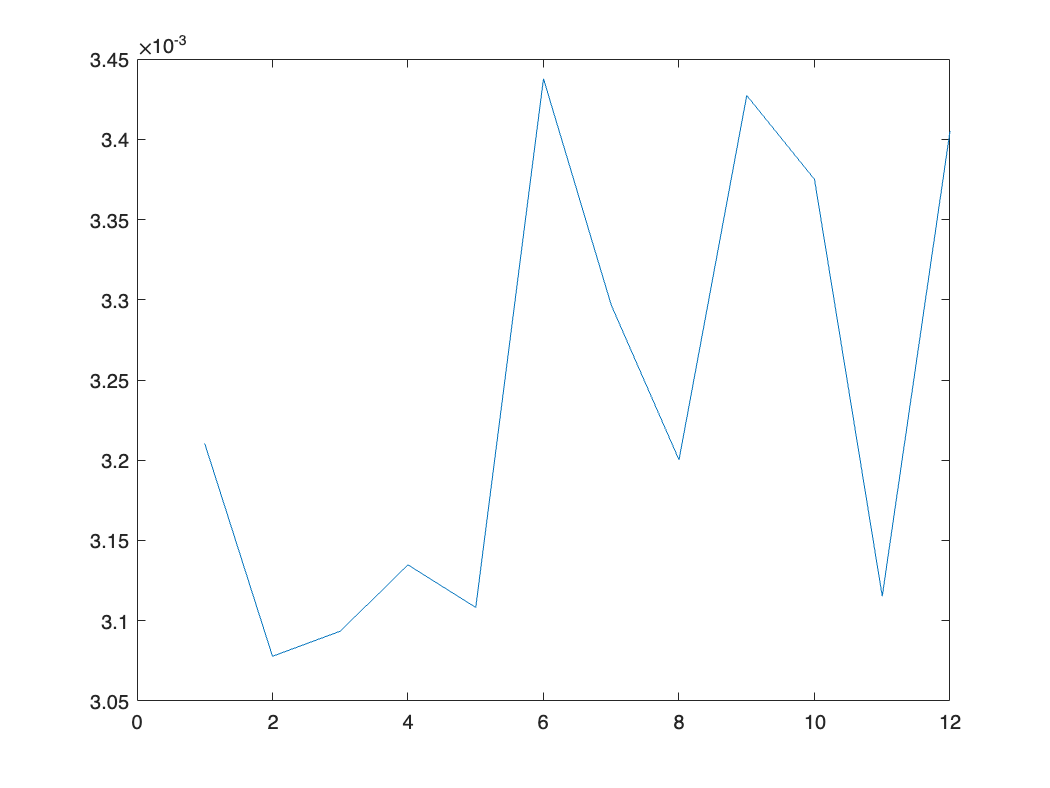


for i = 17:24
    spc_name = [baseName, 'FLIM0', num2str(i), '.mat'];
    load(spc_name);
    base=mean(spcSave.lifetimes{1}(175:238))-DarkCount_mean/numPts;
    tot=sum(spcSave.lifetimes{1})-numPts*base-DarkCount_mean;
    afterpulse_all = [afterpulse_all numPts*base/tot];
    
end

figure
plot(afterpulse_all)

mean(afterpulse_all)

ans = 0.0032

% 175:238; 1:8, 239:256 all 0



base=mean(spc.lifetimes{1}(175:238))-DarkCount_mean/numPts;
tot=sum(spc.lifetimes{1})-numPts*base-DarkCount_mean

tot = 9.6431e+05

numPts*base/tot

ans = 0.0032